
m = size(X,1);
a1 = [ones(m, 1), X];
z2 =  a1 * Theta1';
a2 = sigmoid(z2);
a2 = [ones(m, 1), a2];
z3 =  a2 * Theta2';
a3 = sigmoid(z3);

[~, pred] = max(a3,[], 2);

for i = 1:10
    label_pred(i, :) = pred == i;
end

for i = 1:10
    label(i, :) = y == i;
end

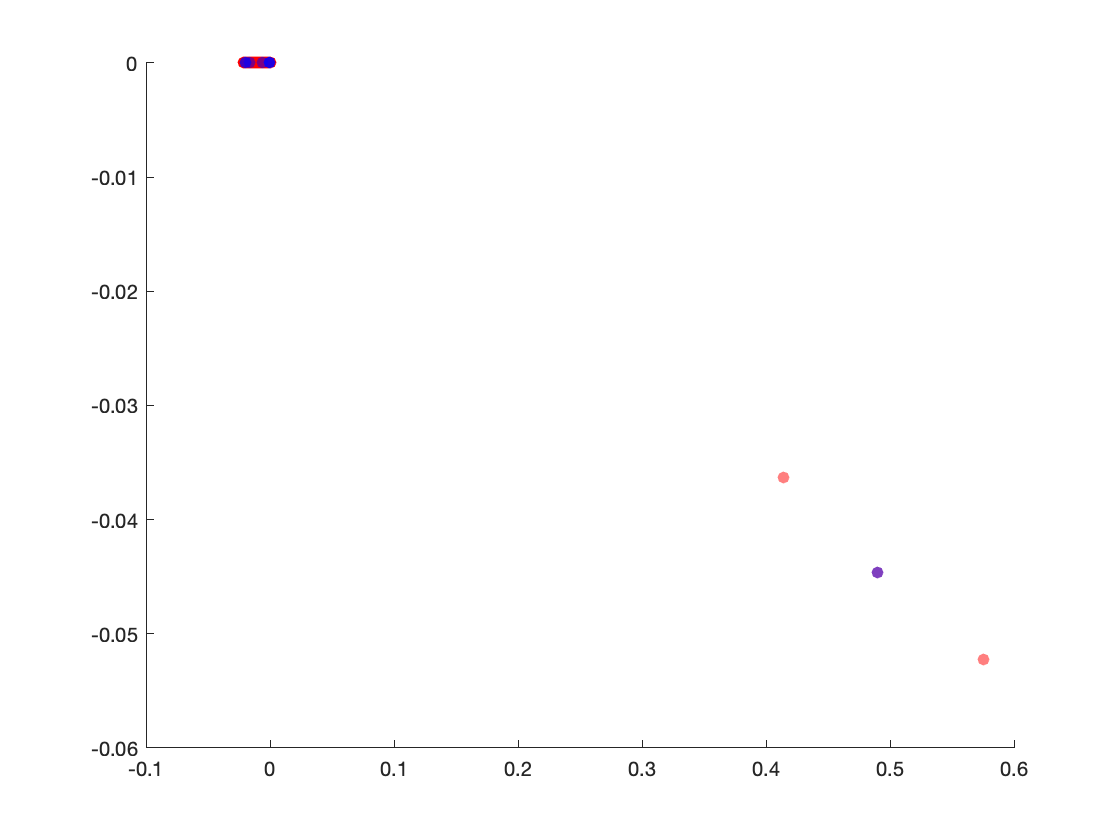

figure,
for i = 10%:10
    scatter(X(label(i,:)',199), X(label(i,:)',200), 'filled','MarkerFaceColor','red','MarkerFaceAlpha',0.5)
    hold on;
    scatter(X((~label_pred(i,:)' & label(i,:)'),199), X((~label_pred(i,:)' & label(i,:)'),200), 'filled','MarkerFaceColor','blue','MarkerFaceAlpha',0.5)
end
hold off;